# Thevenin Battery Model

### Parameters

load('batteryModelNew.mat');
load('soc_ocv_new.mat');
load('currentUAV.mat');

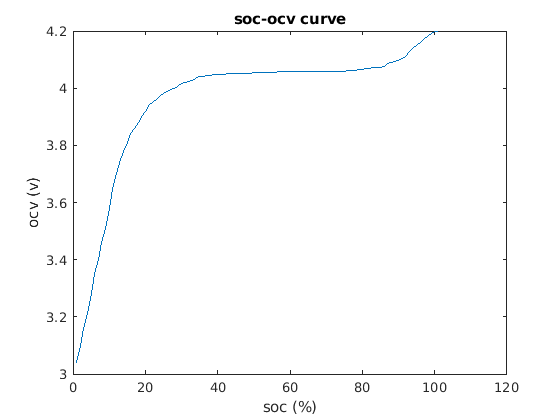

f1 = figure(1); clf;
plot(soc_ocv);
title("soc-ocv curve");
xlabel("soc (%)");
ylabel("ocv (v)");

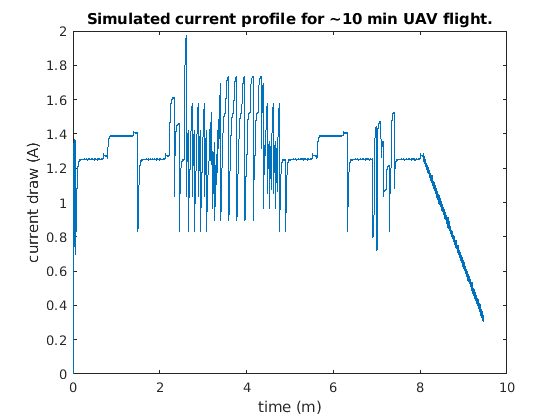

f2 = figure(2); clf; 
srate = 36;
t = (0:length(current) - 1) / srate / 60;
plot(t, current);
ylabel("current draw (A)");
xlabel("time (m)");
title("Simulated current profile for ~10 min UAV flight.");


Q   = battery.QParam; % total capacity in mAh
n   = battery.etaParam; % coulombic efficiency
M   = battery.MParam; % dynamic hysteresis volts factor
Mo  = battery.M0Param; % instant hysteresis volts factor
Ro  = battery.R0Param; % internal resistance
R   = [battery.RCParam(1)]; % diffusion / warburg impedence, pairs with C
C   = [battery.RCParam(2)]; % diffusion / warburg impedence, pairs with R
g   = battery.GParam;  % gamma, tunes decay in hysteresis
dt  = .01; % delta t

### State Variables

z   = state of charge (SOC)

        z[k+1] = z[k] - n[k]*dt*Io[k]

Ir  = current vector through each resistor in R

        Ir[k+1] = Arc*Ir[k] + Brc*Io[k]

h  = hysteresis

        h[k+1] = H[k]*h[k] + (H[k]-1)*sign(Io[k])

### Intermediates

if length(R) ~= length(C)
    error("R and C must be the same length");
end

- Arc, 'A' matrix of the state equation for Ir 

Arc = zeros(length(R));
for i = 1:length(R)
    Arc(i,i) = exp(-dt/(R(i)*C(i)));
end

- Brc, 'B' matrix of the state equation for Ir

Brc = zeros(length(R), 1);
for i = 1:length(R)
    Brc(i,1) = 1 - exp(-dt/(R(i)*C(i)));
end

- H, 'A' matrix (H-1 is 'B' matrix) of state equation for h, H is dynamic!

k = 1; % timestep
Io = .1; % current at time k
H(k) = exp(-abs((n(k)*Io(k)*g*dt)/Q))

H = 1.0000

### State equations

Io = current(1:floor(length(current)/2.5));
t2 = (0:length(Io) -1) / srate / 60;

z = 1.0; % soc
Ir = zeros(length(R), 1);
h = 0.0;
v = ones(length(Io));

soc = zeros(1, length(Io));
v = soc;
for i=1:length(Io)
    z_dot = z - ((n*dt)/Q)*Io(i);
    Ir_dot = Arc*Ir + Brc*Io(i);
    H = exp(-abs((n*Io(i)*g*dt)/Q));
    h_dot = H*h + (H-1)*sign(Io(i));
    z = z_dot;
    Ir = Ir_dot;
    h = h_dot;
    soc(i) = (z + 31.8816) /(1.0 + 31.8816);
    idx = ceil(soc(i)*100) +1;
    v(i) = (soc_ocv(idx) + Mo*sign(Io(i)) + M*h - sum(R*Ir) - Ro*Io(i));
  %  soc(i) = z;
end


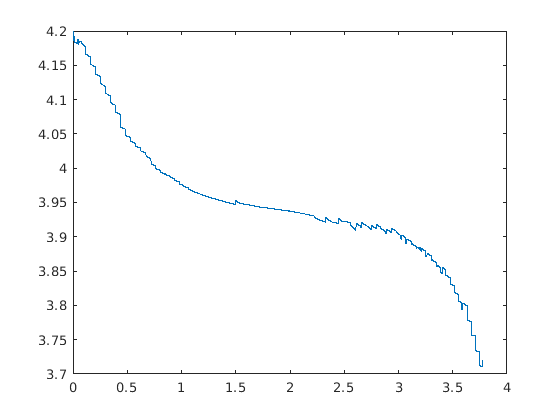

plot(t2, v);

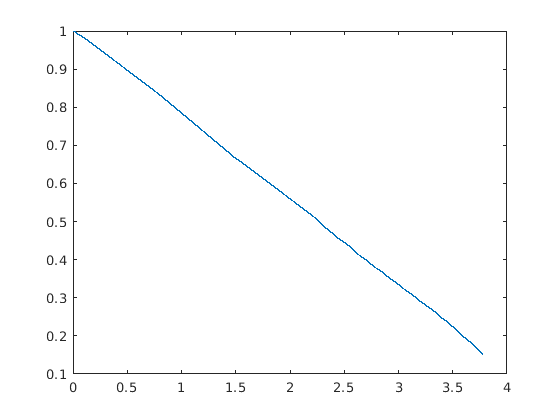

plot(t2, soc);

soc_ocv(95)

ans = 4.1500

soc_ocv(31)

ans = 4.0200

soc_ocv(15)

ans = 3.8100